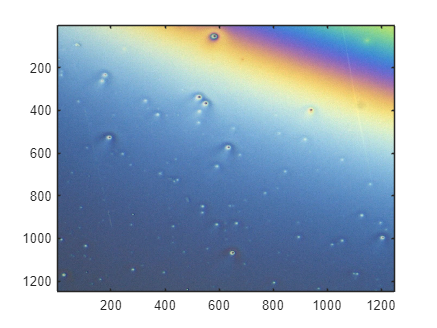

clear
clc
test = imread('1.jpg');
image(test);

load('rm_f.mat');
rgb = transpose(rgbmatrix(:,1:400))/256;
rgb(rgb>1) = 1;
X = rgb2ind(test,rgb);

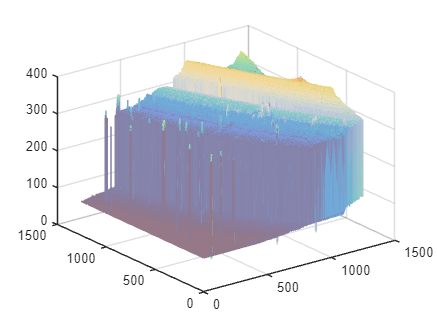

mesh(imrotate(X,-90))
% zlim([0 500])
% h = fspecial("gaussian");
% ma = filter2(h,X);
% mesh(ma)
% zlim([0 1000])
customCMap = uint8(rgbmatrix(:,1:400)');
colormap(customCMap);

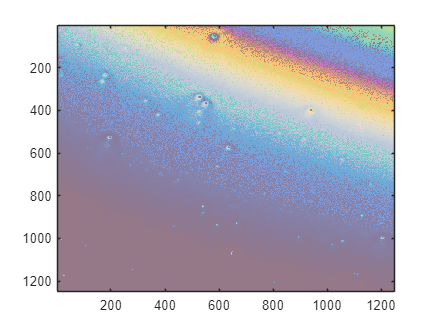

imagesc(X)

% colorbar

% C(:,:,1) = customCMap(:,1)'.*uint8(ones(100,1));
% C(:,:,2) = customCMap(:,2)'.*uint8(ones(100,1));
% C(:,:,3) = customCMap(:,3)'.*uint8(ones(100,1));
% C_g = rgb2gray(C);
% image(C_g)